# Thermal Evolution of Primordial Planetesimals

clear, clc, close all
set_demo_defaults

## Intro to plantesimals in early solar system

Planetesimals are small, rocky, and icy planetary bodies that formed and evolved in the early solar system. Planetesimals play at least two important roles in planetary science. First, as the first generation of planetary objects, they served as the fundamental building blocks of planets. They represent a critical but still enigmatic stage in planetary growth. Planetesimals, and their modern day relics – asteroids, comets and Kuiper-belt objects – experienced a much broader range of thermal histories than planets; these diverse conditions produced a diversity of igneous end states, from unmelted bodies, to partially melted bodies, to fully molten and differentiated objects (Weiss & Elkins-Tanton, 2017). 

Several extinct radioactive isotopes that may have contributed to heat generation in early-forming bodies include $^{26}$Al, $^{60}$Fe, $^{53}$Mn, $^{146}$Sm, and $^{182}$Hf. Aluminum, however, dominates the heat budget. With a half-life of 717,000 years and at the canonical level of 5.23 ± 0.13 × 10$^{-5}$ $^{26}$Al/$^{27}$Al (Jacobsen *et al.*, [2008](https://www-cambridge-org.ezproxy.lib.utexas.edu/core/books/planetesimals/silicate-melting-and-volatile-loss-during-differentiation-in-planetesimals/216EBC4166F9219DDEB5EA50740C57FF/core-reader#REFe-r-425)), the energy output of decaying $^{26}$Al is sufficient to cause silicate melting in planetesimals that accrete to more than ~20 km radius in less than ~2 Myr after beginning of the solar system.

The beginning of the solar system is generally take as the age of the first high-T condensated from the solar nebula, the so-called Calcium Aluminum Inclusions (CAIs), currently dated to ﻿4567.30$\pm$0.16 million years ago (Connelly et al., [2012](https://science.sciencemag.org/content/338/6107/651)). In the early solar system everything is referenced relative to this event and times are referred to as "since CAI".

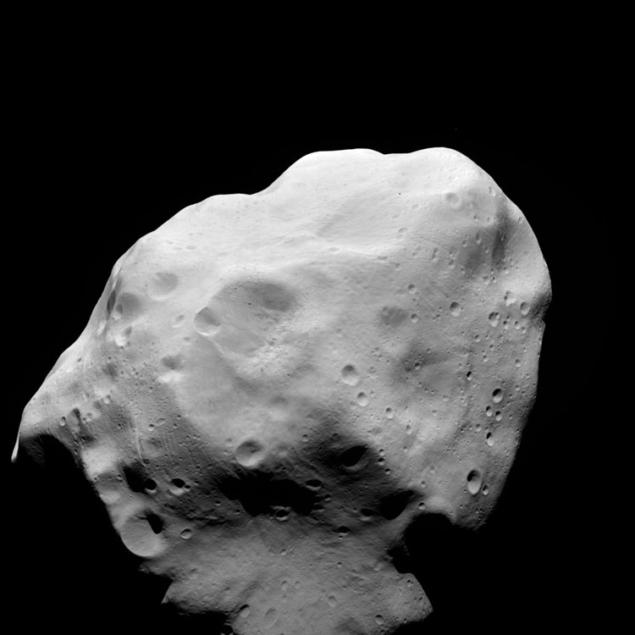

The image shows asteroid [21 Lutetia](https://en.wikipedia.org/wiki/21_Lutetia), visited by the ESA Rosetta space probe in 2011. It measures about 100 kilometers in diameter and has a high density of 3400 kg/m$^3$, suggesting it contains metal-rich, partially differentiated interior. The most heavily cratered surfaces  have a crater retention age of about 3.6 ± 0.1 billion years, suggesting it is a primordial planetesimal left over from the formation of the solar system. The composition of Lutetia suggests that it formed in the inner Solar System, among the terrestrial planets, and was ejected into the asteroid belt through an interaction with one of them.

## Simple thermal model for planetesimals

Here we will compute the thermal evolution of a primordial planetesimal. To do so we make several simplifying assumptions:

- Instantaneous accreation at $t_0$ with radius $R$.

- Homogeneous composition, so that all material paramters are constant.

- Constant surface temperature of $T_s$.

- Only conductive heat transport.

Hence we are solving the following transient heat conduction problem in spherical geometry

$\rho c_p\frac{\partial T}{\partial t} - \nabla\cdot\left[\kappa\nabla T\right] = \rho H_0 e^{-\lambda t}$ on $r\in\left[0,\,R\right]$ and $t \in \left[t_0,\, \infty\right)$

with the boundary conditions $\left.\mathbf{q}\cdot\hat{\mathbf{r}}\right|_{r=0} = 0$ and $T(z=R,t) = T_s$. Here the radiogenic heating by the decay of the extinct radio nuclide $^{26}$Al is described by: $H_0$, the initial heat production, $\lambda$ is the decay constant of $^{26}$Al. $t$is the time since the formation of Calcium-Aluminum-rich Inclusions (CAI's).

Here we introduce the time since planetesimal formation, $\tau = t-t_0$, so that radiogenic heating term becomes


$$\rho H_0 e^{-\lambda (\tau+t_0)} = \rho H e^{-\lambda t_0}  e^{-\lambda \tau}=A_0e^{-\lambda \tau}$$
 

where $A_0 = \rho H_0e^{-\lambda t_0}$ is the heat production per unit volume at the time of accretion. Hence we have the following governing equation 

$\rho c_p\frac{\partial T}{\partial \tau} - \nabla\cdot\left[\kappa\nabla T\right] = A_0(t_0) e^{-\lambda \tau}$ on $r\in\left[0,\,R\right]$ and $\tau \in \left[0,\, \infty\right)$

The analytic solution for this problem is given by


$$T= T_s+\frac{DA_0}{\kappa \lambda}e^{-\lambda \tau}\left(\frac{R \sin\left(\sqrt{\lambda/D}r\right)}{r \sin\left(\sqrt{\lambda/D}\right)}-1\right)+\frac{2R^3 A_0}{r\pi^3 \kappa}\sum_{n=1}^\infty \frac{(-1)^n}{n(n^2-\lambda R^2/(D\pi^2))}\sin(n\pi r/R)e^{-Dn^2\pi^2 \tau/R}$$


where $D=\kappa/(\rho c_p)$is the thermal diffusivity and $A_0$is defined above.

This formula is sufficiently complicated to give little physical insight, therefore we consider also the simpler case of the heating of and insulated sphere. This is given by the following ODE, obtained by dropping the conductive heat transfer term

$\rho c_p\frac{\partial T}{\partial \tau} = A_0(t_0) e^{-\lambda \tau}$ and $\tau \in \left[0,\, \infty\right)$

which can be integrated to give upper bound on the temperature in the planetesimal


$$T_{ins} = T_0+\frac{A_0}{ \lambda\rho c_p}\left(1-e^{-\lambda \tau}\right)$$


here $\Delta T = \frac{A_0}{ \lambda\rho c_p}$ is the overall temperature increase.

## Thermal evolution of Asteroid 21 Lutetia

We can apply this solution to ateroid 21 Lutetia to constrain it's formation age.

%% Physical parmeters
yr2s = 60^2*24*365.25; % [s/yr] number of seconds per year

% Primary parameters (from Hevey and Sanders 2006, Table 1)
Param.k   = 2.1;            % [W/(m K)] Thermal conductivity 
Param.cp  = 837;            % [J/(kg K)] specific heat capacity 
Param.rho = 3400;           % [kg/m3] density 
Param.lam = 9.5e-7/yr2s;    % [1/s] decay constant converted from 1/yr to 1/s
Param.H0  = 1.9e-7;         % [W/kg] initial power per unit mass
Param.T0  = 250;            % [K] initial and surface temperature
Param.R   = 100e3;           % [m] Planetesimal radius 
Param.t0  = 2.25e6*yr2s;     % [s] accretion time

% Derived parameters
Param.kappa = Param.k/(Param.cp*Param.rho);                        % [m/s2] thermal diffusivity 
Param.A0    = @(t0) Param.rho*Param.H0*exp(-Param.lam*Param.t0);   % [W/m3] initial power per unit volume at accretion
Param.t_half = log(2)/Param.lam;                                   % [s] Half-life of Al-26
Param.T_c = Param.A0(Param.t0)*Param.R^2/Param.k;

% Analytic solns.
DT = Param.H0*exp(-Param.lam*Param.t0)/(Param.lam*Param.cp);
T_insulated = @(tau) Param.T0 + DT*(1-exp(-Param.lam*tau));

The plot on the left shows the radial temperature profiles through the planetesimal. Early times are shown in red and lter times are shown in yellow. Duing the initial warming the temperature profile in the interior is almost flat with only a ~20 km thick thermal boundary layer at the surface. The figure on the right shows the evolution of the central temperature (blue) and the bounding solution for and isolated sphere (red). This illustrated the extreemly rapid heating over a few million years and the slow long cooling over 150 million years. It also show that the center of a planetesimal with these parameters reaches the temperatures comparable to an isolated sphere.

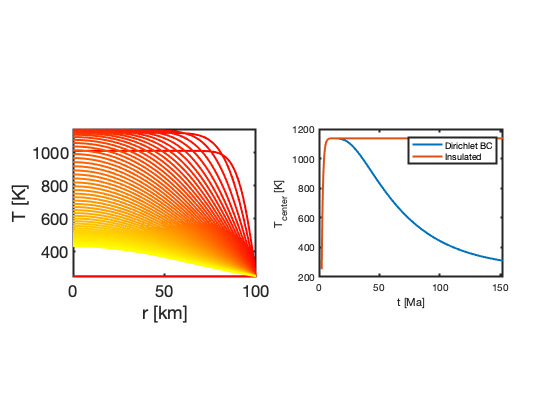

Nt = 5e1;
tau_vec = linspace(0,100e6,Nt)'*yr2s;
rvec = linspace(1,Param.R,1e2);
T = PlanetesimalAnalytic(Param,tau_vec,rvec,1e3);

tau_cen = linspace(0,150e6,1e3)'*yr2s;
T_cen = PlanetesimalAnalytic(Param,tau_cen,1,1e3);

subplot 121
map = colormap(autumn(Nt));
for i=1:Nt; plot(rvec/1e3,T(:,i)','-','color',map(i,:)), hold on; end
pbaspect([1 .8 1])
xlabel 'r [km]'
ylabel 'T [K]'

subplot 122
plot((tau_cen+Param.t0)/yr2s/1e6,T_cen), hold on
plot((tau_cen+Param.t0)/yr2s/1e6,T_insulated(tau_cen))
pbaspect([1 .8 1])
xlabel 't [Ma]'
ylabel 'T_{center} [K]'
legend('Dirichlet BC','Insulated')

## Numerical Solution

Here we use the central temperature computed numerically to compare with the analytic solution. Again we have an exponetialy declining heat production term, similar to the continental geotherm studied previously, but this time the decay is with time not depth. Given the overal time scalse of 100's of millions of years the decay of $^{26}$Al is very rapid. Similar to the geotherm undersampling this rapid decay with coarse time stepping leads to surprisingly large errors. Again we can eliminate these by properly averaging the source term over the time step


$$\langle f_s^n\rangle =\frac{1}{\Delta \tau}\int_{t^n}^{t^{n+1}}A_0e^{-\lambda \tau}\mathrm{d}\tau = \frac{A_0}{\lambda\Delta \tau}\left(e^{-\lambda  t^n}-e^{-\lambda t^{n+1}}\right)$$


Using the properly averaged source term leads to drastic improvements of the solution and surprisingly good results with relatively course time steps. This is because the total energy added to the system is now the right one and independent of the time step chosen.

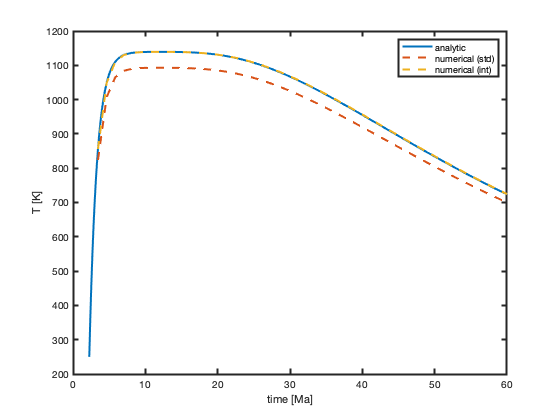

Nt = 50;
tmax = 60e6*yr2s;
dt = tmax/Nt;

Grid.geom = 'spherical_r';
Grid.xmin = 0;  Grid.xmax = Param.R; Grid.Nx = 2e3;
Grid = build_grid(Grid);

% Discrete Operators
[D,G,I] = build_ops(Grid); 
M = Param.rho*Param.cp*I;
IM = @(theta,dt) M - dt*(1-theta)*Param.k*D*G;
EX = @(theta,dt) M + dt*theta*Param.k*D*G;
fs_theta = @(t) Param.A0(Param.t0)*exp(-Param.lam*t)*ones(Grid.Nx,1);

% BC's
BC.dof_dir   = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g         = Param.T0;
BC.dof_neu   = [];
BC.dof_f_neu = [];
BC.q         = [];
[B,N,fn] = build_bnd(BC,Grid,I);

% Standard r.h.s.
theta = 0.5;
u = Param.T0*ones(Grid.Nx,1); ucen = zeros(Nt,1); time = ucen;
for i=1:Nt
    time(i) = dt*i;
    tau_theta = theta*(i-1)*dt + (1-theta)*i*dt;
    u = solve_lbvp(IM(theta,dt),EX(theta,dt)*u+dt*(fs_theta(tau_theta)+fn),B,BC.g,N);
    ucen(i) = u(1); 
end

% Integrated r.h.s.
u = Param.T0*ones(Grid.Nx,1); ucen_int = zeros(Nt,1); time = ucen;
for i=1:Nt
    time(i) = dt*i;
    tau_theta = theta*(i-1)*dt + (1-theta)*i*dt;
    told = (i-1)*dt; tnew = i*dt;
    u = solve_lbvp(IM(theta,dt),EX(theta,dt)*u+dt*(fs_int(told,tnew,Param,Grid)+fn),B,BC.g,N);
    ucen_int(i) = u(1); 
end

figure
plot((tau_cen+Param.t0)/yr2s/1e6,T_cen,'-'), hold on
plot((time+Param.t0)/yr2s/1e6,ucen,'--')
plot((time+Param.t0)/yr2s/1e6,ucen_int,'--')
xlabel 'time [Ma]'
ylabel 'T [K]'
xlim([0 60])
legend('analytic','numerical (std)','numerical (int)')

# Auxillary functions

function T = PlanetesimalAnalytic(Param,tau_vec,rvec,N)
% author: Marc Hesse
% date 1 Aug 2019, 17 Feb 2020
% INPUT:
% Param = structure containing physical paramters
% tau_vec = [s] Nt by 1 column vector containing times (since formation) at 
%           which the solution is evaluated
% rvec = [m] Nr by 1 colum vector with radial locations of the solution
% N = [1] number of terms in series solution
% OUTPUT:
% T = [K] Nr by Nt matrix of temperature profiles 
% Description:
% Dimensional analytic solution for the heating of a sphere with an
% exponentially decaying heat source.

% Unpack Param for readability
t0 = Param.t0;              % [s] accretion time    
kappa = Param.kappa;        % [m/s2] thermal diffusivity 
k = Param.k;                % [W/(m K)] Thermal conductivity 
T0 = Param.T0;              % [K] initial and surface temperature
A0 = Param.A0(t0);    % [W/m3] initial power per unit volume at accretion
lam = Param.lam;            % [1/s] decay constant converted from 1/yr to 1/s
R = Param.R;                % [m] Planetesimal radius 

if max(rvec) > R; error('rvec is exceeds R!'); end

[tau,r] = meshgrid(tau_vec,rvec);

term1 = R*sin(r*sqrt(lam/kappa))./(r*sin(R*sqrt(lam/kappa)));
term2 = 2*R^3*A0./(r*pi^3*k);
term3 = @(n) (-1)^n/((n*(n^2-lam*R^2/(kappa*pi^2))));

T = T0 + kappa*A0/(k*lam)*exp(-lam*tau).*(term1-1);

for n=1:N
    T = T + term2*term3(n).*sin(n*pi*r/R).*exp(-kappa*(n*pi)^2*tau/R^2);
end
end